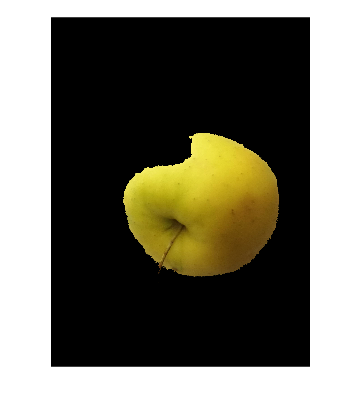

im1=imread('F03.jpg');
 %imshow(im1)
 im2=im2double(im1);
 I=rgb2gray(im2);
 maximum= max(max(I));
 minimum = min(min(I));
 im3 = (im1-minimum)/(maximum-minimum);
 im3=im2double(im3);
 %imshow(im3)
 im4=rgb2hsv(im3);
 im4=rgb2gray(im4);
 %imshow(im4)
 threshold=0.49;
 im5=(im4>threshold);
 im5 = imfill(im5, 'holes');
 %imshow(im6)
 %mask=bwlabel(im6);
 
%imshow(mask)
im7=im3.*im5;
%im7=im3;
%im7(~mask)=0;
imshow(im7)

R=im7(:,:,1);
r=R(R>0);
r=r(r<1);
Rmean=mean(mean(r))

Rmean = 0.6546

G=im7(:,:,2);
g=G(G>0);
g=g(g<1);
Gmean=mean(mean(g))

Gmean = 0.5647

B=im7(:,:,3);
b=B(B>0);
b=b(b<1);
Bmean=mean(mean(b))

Bmean = 0.1225

vec1=[Rmean Gmean Bmean]

vec1 =     0.6546    0.5647    0.1225



vecapple = [0.7485 0.6101 0.1436]

vecapple =     0.7485    0.6101    0.1436


vectang= [0.7303 0.2522 0.0794]

vectang =     0.7303    0.2522    0.0794
